# FIR Deconvolution model

*Please contact Ted (Theodore.Huppert@StonyBrookMedicine.edu) or Hendrik (hes73@pitt.edu) to request more demos, suggestions, feedback, etc. We will update this script as needed. *

This example demonstrates: 

- Simulating task-based fNIRS data

- Preprocessing the simulated data

- Estimating subject-level responses using an FIR model

- Estimating group-level responses

- Reconstructing HRFs and testing temporal contrasts

For simplicity, this example uses a fixed-effects group model. 

clear;
clc;
rng(1);  % Make the simulated example reproducible.

%% Generate Simulated Data
nSubjects = 10;

for i = 1:nSubjects
    raw(i) = nirs.testing.simData([], ...
        @(t) nirs.testing.blockedStimDesign(t, 5, 15, 2));
    % task-based 5s duration, 15s between onset, and 2 conditions
end

% Confirm the argument definitions in your installed toolbox:
% help nirs.testing.blockedStimDesign
%
% Inspect the generated stimulus names and timing:
disp('Simulated stimulus names:');

Simulated stimulus names:


disp(raw(1).stimulus.keys);

    {'A'}    {'B'}




%% Basic Preprocessing
job = nirs.modules.OpticalDensity();

job = nirs.modules.Resample(job);
job.Fs = 1;  % Low sampling rate for a faster demonstration.

job = nirs.modules.BeerLambertLaw(job);

Hb = job.run(raw);

## First-level Analysis: FIR model

Unlike a canonical HRF model, an FIR model estimates separate coefficients across a series of time bins, allowing a flexible shape. 

% isIRF = true:
%   Estimates an impulse response using the stimulus time course,
%   including its duration.
%
% isIRF = false:
%   Uses stimulus onsets to estimate the event-related response directly.
%   Choose a window long enough to include the task response and recovery.

basis = nirs.design.basis.FIR();
basis.isIRF = false;
basis.binwidth = 1;  % One sample per bin = 1 second at 1 Hz.
basis.nbins = 20;    % 20-second window; bin lags: 0, 1, ..., 19 seconds.

% Twenty bins cover a 20-second response window.
% At 1 Hz with binwidth = 1, each bin represents 1 second.
% The bin lags are approximately:
%   Bin:       1  2  3  4  5  ...  18  19  20
%   Lag (s):   0  1  2  3  4  ...  17  18  19
%
% This window captures the 5-second stimulus and subsequent recovery.
% Overlapping responses are allowed in a deconvolution model, provided
% the experimental design supports estimation of the coefficients.

job = nirs.modules.AR_IRLS();
job.basis('default') = basis;

Stats = job.run(Hb);

................................Finished    1 of   10.
................................Finished    2 of   10.
................................Finished    3 of   10.
................................Finished    4 of   10.
................................Finished    5 of   10.
................................Finished    6 of   10.
................................Finished    7 of   10.
................................Finished    8 of   10.
................................Finished    9 of   10.
................................Finished   10 of   10.


**Group Level**

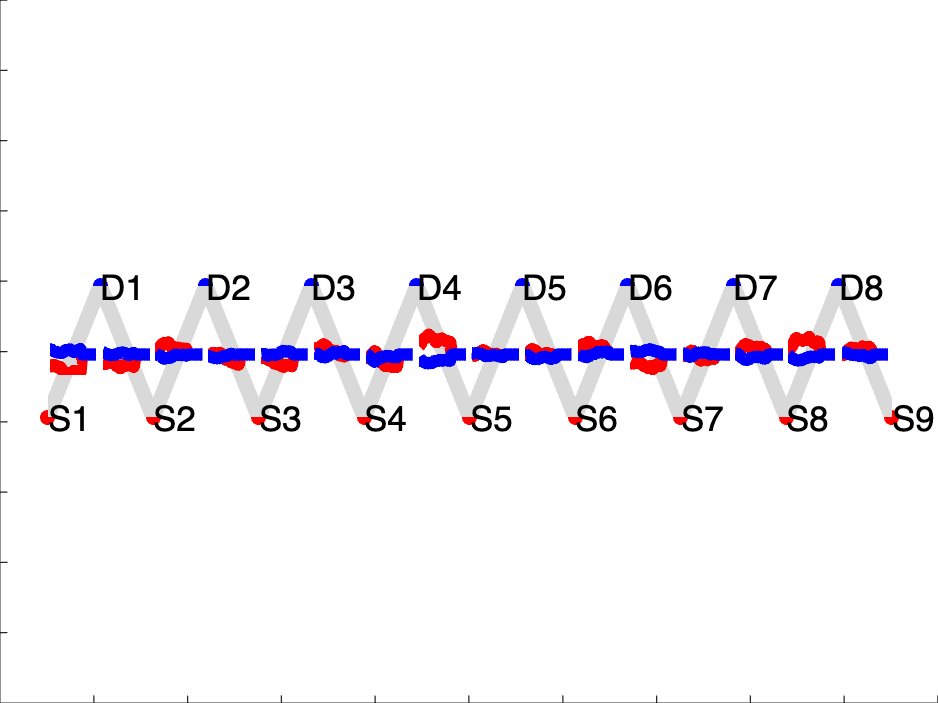

% Group-Level Analysis
job = nirs.modules.MixedEffects();

% Estimate a separate group coefficient for every condition/FIR bin.
% "-1" removes the intercept.
%
% This formula has no random-effects term, so it is a fixed-effects model.
job.formula = 'beta ~ -1 + cond';

GroupStats = job.run(Stats);

%% Check Condition Names Before HRF Reconstruction
% HRF reconstruction requires group coefficient names to match the
% first-level condition names.
%
% Some toolbox versions retain a "cond_" prefix after group analysis.
% Remove that prefix only if doing so produces an exact match.
%
% This adjustment is specific to the simple model above. Do not apply it
% blindly to models containing group interactions or other predictors.

subjectConditions = Stats(1).conditions;
groupConditions = GroupStats.conditions;

GroupStatsForHRF = GroupStats;

if ~isequal(sort(groupConditions(:)), sort(subjectConditions(:)))

    correctedConditions = regexprep(groupConditions, '^cond_', '');

    if isequal(sort(correctedConditions(:)), ...
               sort(subjectConditions(:)))

        GroupStatsForHRF.variables.cond = regexprep( ...
            GroupStatsForHRF.variables.cond, '^cond_', '');

    else
        disp('First-level conditions:');
        disp(subjectConditions);

        disp('Group-level conditions:');
        disp(groupConditions);

        error(['Group and first-level condition names do not match. ' ...
               'Inspect the names displayed above.']);
    end
end

%% Reconstruct and Plot Group HRFs
% Reconstruct the time courses from the fitted FIR coefficients.
HRF = GroupStatsForHRF.HRF;


% Display responses over the probe layout.
nirs.viz.plot2D(HRF);

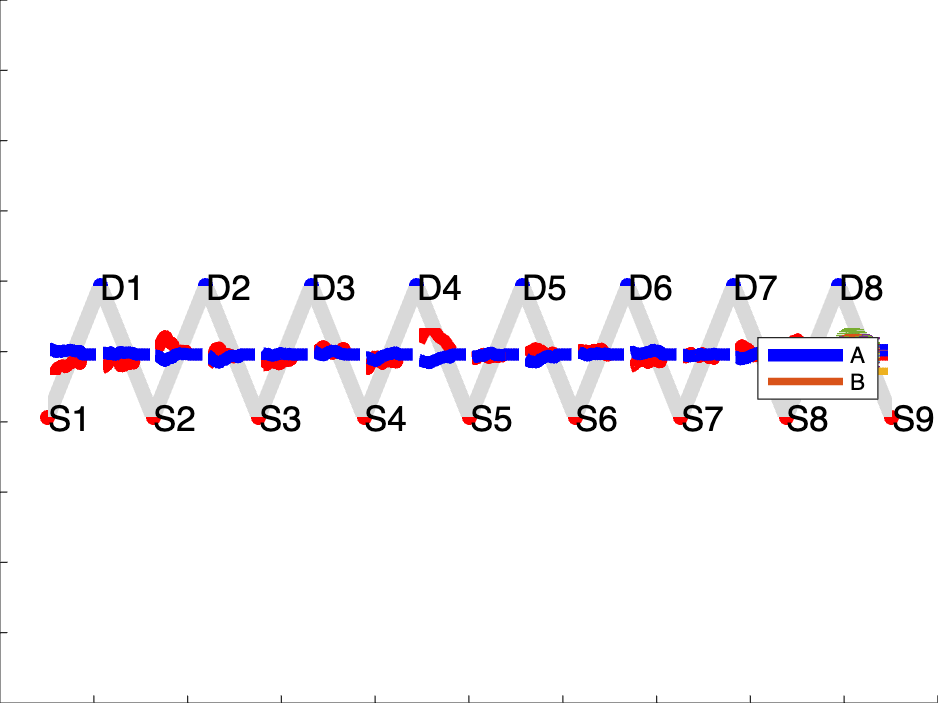


% Display the reconstructed time courses using the Data plotting method.
HRF.draw;


%% Select a Condition for Temporal Contrasts
% Use an actual stimulus name rather than assuming it is named "A".
stimNames = Hb(1).stimulus.keys;
conditionName = stimNames{1};

fprintf('Temporal contrasts for condition: %s\n', conditionName);

Temporal contrasts for condition: A


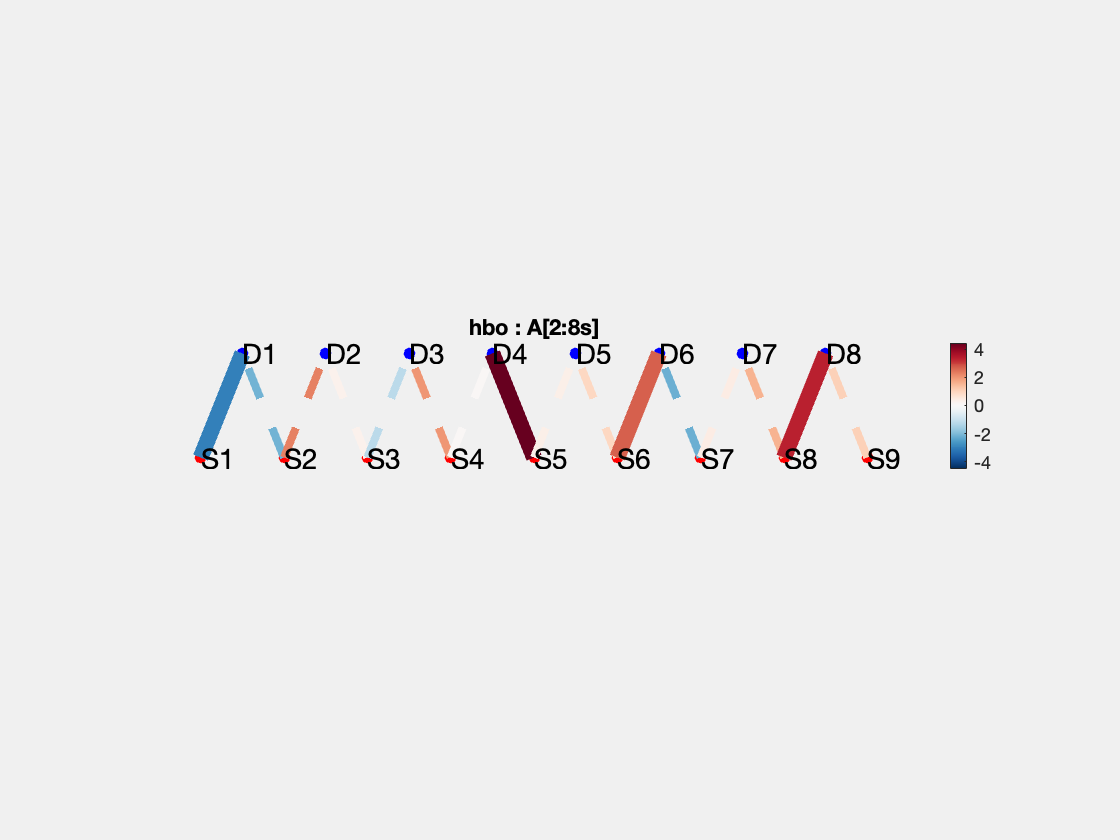

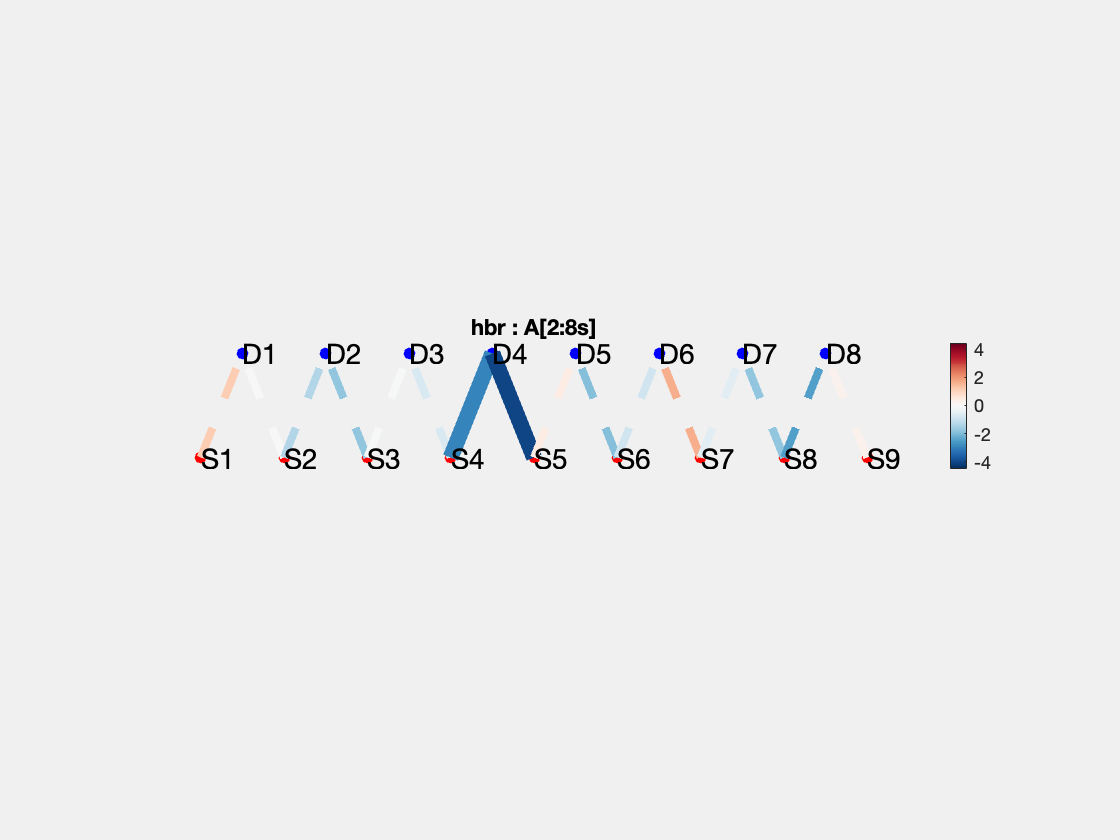


%% Contrast 1: Time Window Specified in Seconds
% Test a weighted combination of the FIR coefficients associated with
% the 2-8 second window against zero.
%
% Window boundaries are represented at the available FIR resolution.
% This is one contrast across the window, not a separate test at each time.

contrastSeconds = sprintf('%s[2:8s]', conditionName);
ContSeconds = GroupStatsForHRF.ttest({contrastSeconds});
ContSeconds.draw('tstat', [], 'q<0.05');

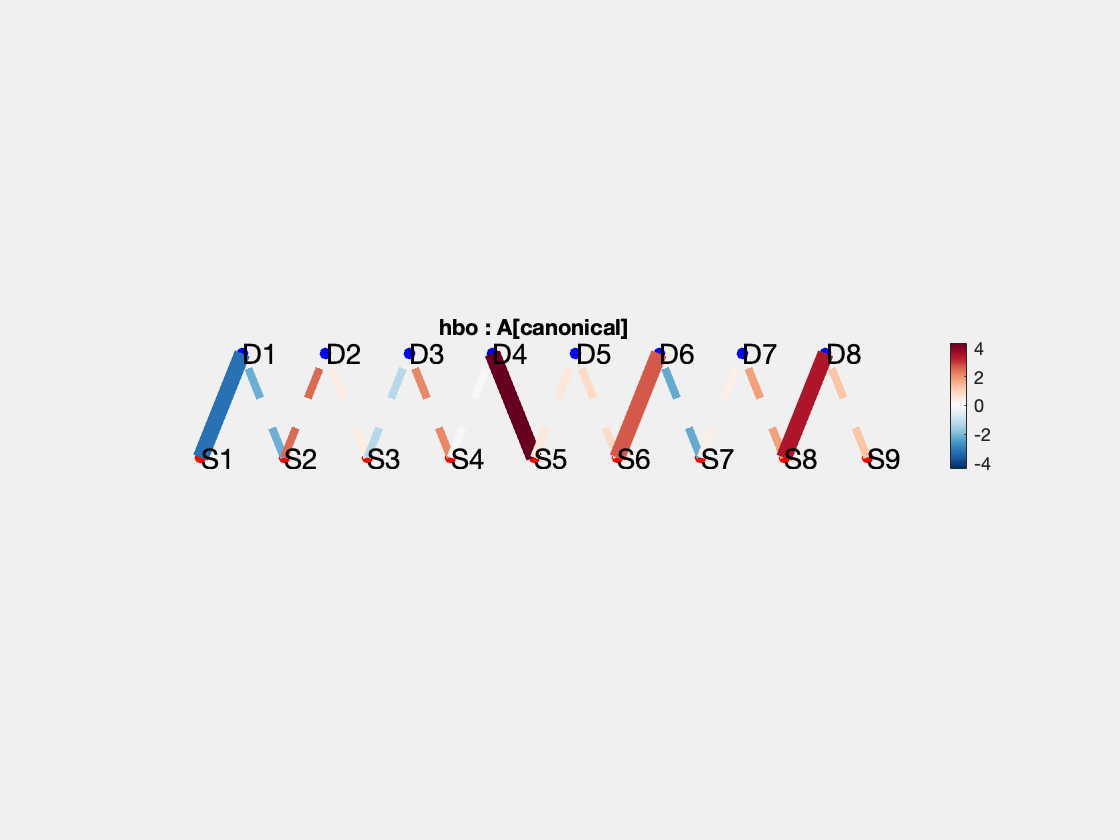

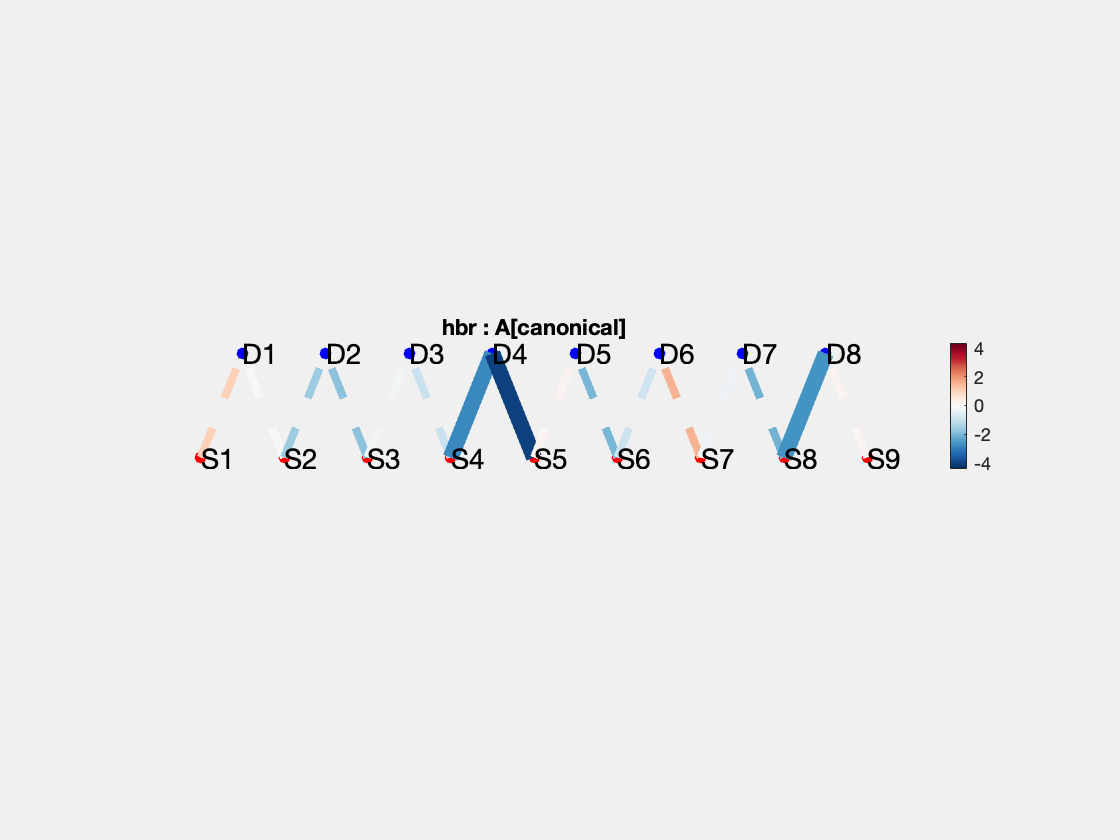


%% Contrast 2: Canonical-HRF-Weighted Contrast
% Weight the FIR coefficients using a canonical HRF shape.
% This tests a canonical-shaped component of the estimated response;
% it does not refit the data with a canonical basis.

contrastCanonical = sprintf('%s[canonical]', conditionName);
ContCanonical = GroupStatsForHRF.ttest({contrastCanonical});
ContCanonical.draw('tstat', [], 'q<0.05');

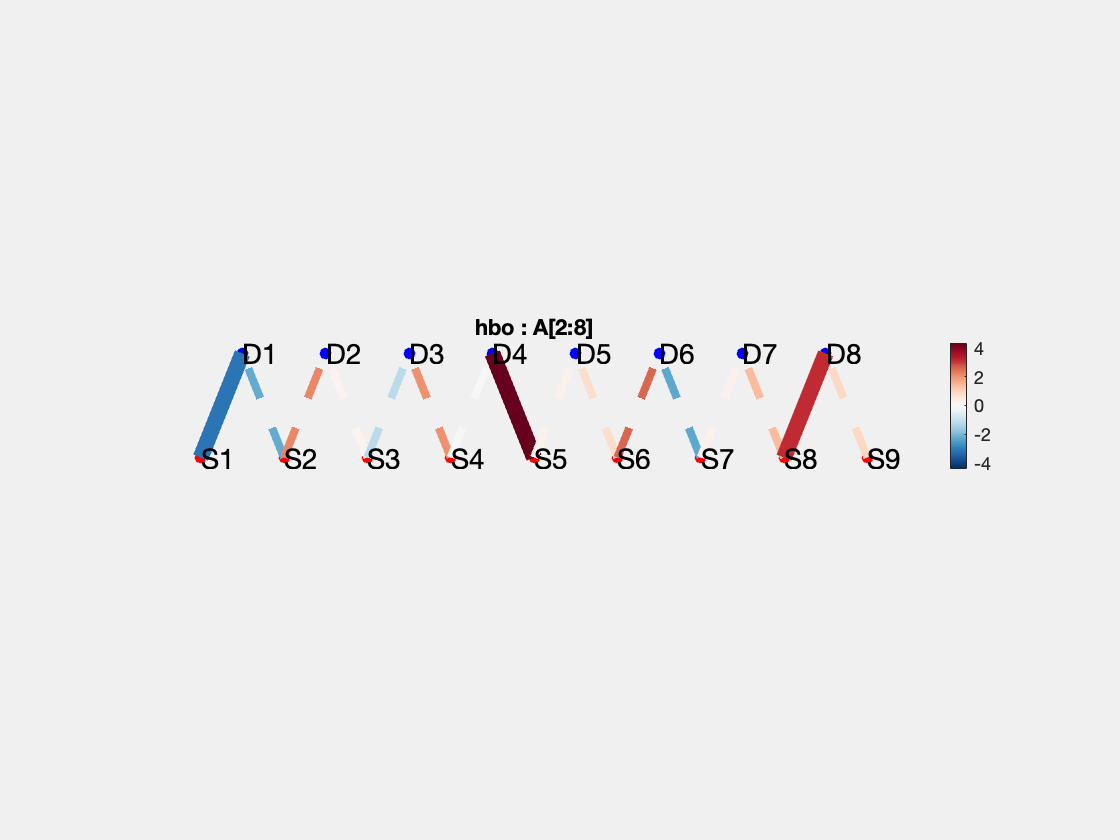

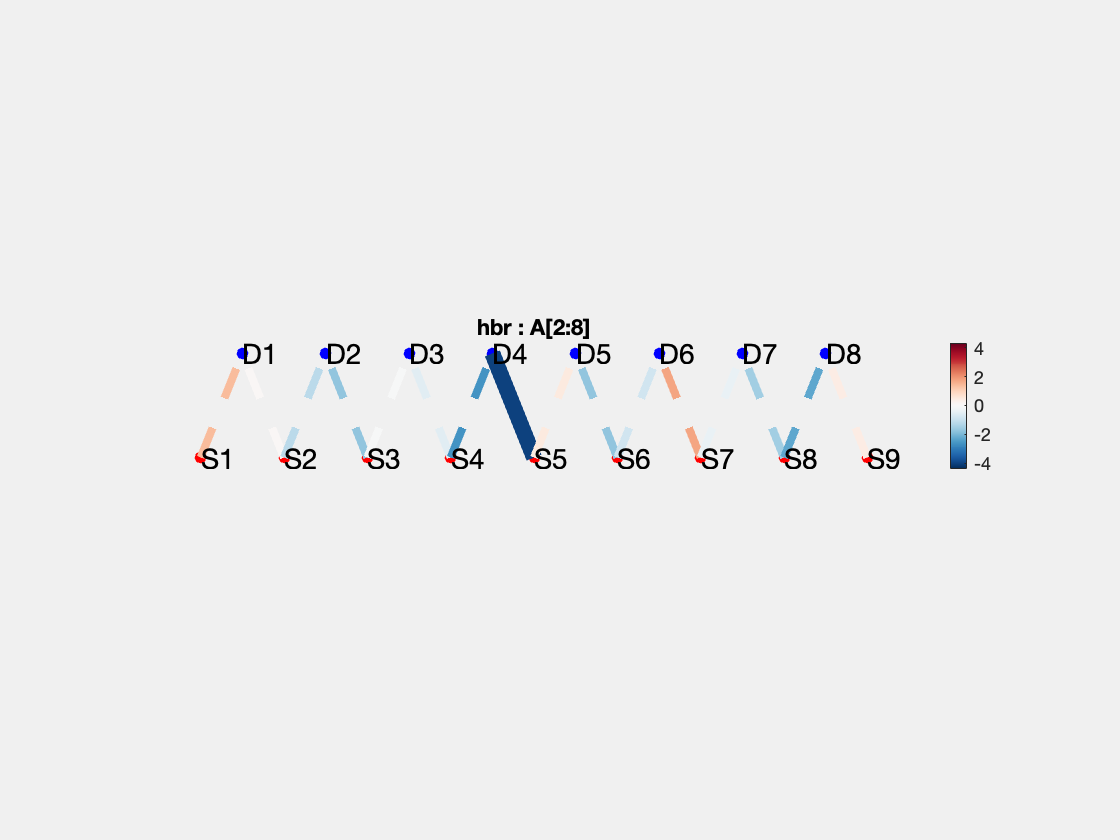


%% Contrast 3: Window Specified by FIR Bin Number
% Select FIR bins 2 through 8.
% At 1 Hz with binwidth = 1, these correspond approximately to
% lags of 1, 2, 3, 4, 5, 6, and 7 seconds.
%
% Bin numbers start at 1, whereas time lags start at 0.
% Therefore, this differs from the 2-8 second contrast above.

contrastBins = sprintf('%s[2:8]', conditionName);
ContBins = GroupStatsForHRF.ttest({contrastBins});
ContBins.draw('tstat', [], 'q<0.05');


% All three contrasts test the selected condition against zero.
% None directly compares the two task conditions.
%
% The plotting threshold displays results meeting q < 0.05.
% It does not establish correction across all three separate analyses.